# Module 9:  Application of Matlab in Numerical Analysis III -- Numerical Solution of Ordinary Differential Equations (ODE)

## **1. Mathematical Background**

### **1.1 Concept of **[ODE](https://en.wikipedia.org/wiki/Ordinary_differential_equation)

Mathematical descriptions of change use differentials and derivatives. 

Differentials, derivatives, and functions become related via equations, such that a differential equation is a result that describes dynamically changing phenomena, evolution, and variation.

An ordinary differential equation (ODE) is an equation that involves some ordinary derivatives of a function (we have some constraints between the function itself and its derivatives). 

Often, our goal is to solve an ODE, i.e., determine what function or functions satisfy the equation.

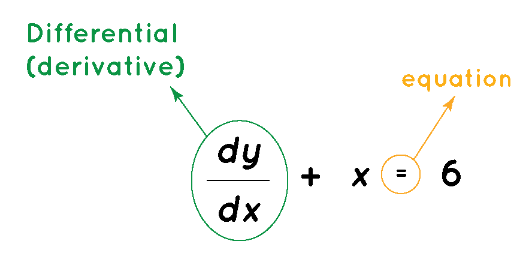(source: https://www.cuemath.com/calculus/differential-equation/)

***Example 1: the simplest ODE.***

Let $x\left(t\right)$ be a function of $t$ that satisfies the (first order) ODE: $\frac{\textrm{dx}}{\textrm{dt}}=0$.

***Questions: What is ***$x\left(t\right)$***? Is ***$x\left(t\right)$*** uniquely determined by this ODE?***

***Example 2: a slightly more complicated ODE.***

Let $x\left(t\right)$ be a function of $t$ that satisfies the (first order) ODE: $\frac{\textrm{dx}}{\textrm{dt}}=x$, and one solution is $x\left(t\right)=e^t$ -- is this the only solution? 

***Example 3: a simple second order ODE (optional).***

$\frac{d^2 x}{{\textrm{dt}}^2 }=-x$ is a second order ODE, and one solution is $x\left(t\right)=\sin \left(t\right)$.

**Here we only focus on the initial-value problem of first order autonomous ODEs (ODEs + initial conditions):**


$$\frac{\mathit{\mathbf{d}}}{\textrm{dt}}x\left(t\right)=\mathit{\mathbf{f}}\left(x\left(t\right)\right),\;x\left(0\right)=x_0$$


( autonomous ODE: the R.H.S. depends solely on the system's current state $\mathit{\mathbf{f}}\left(x\left(t\right)\right)$, no parameter $t$ appears. )

Physical interpretation: $x\left(t\right)$ is the location of particle at time $t$, and $\mathit{\mathbf{f}}\left(x\left(t\right)\right)$ is the velocity at location $x$. The ODE describes the "physical law" of particle's movement, and the solution of ODE is indeed the trajectory of particle.

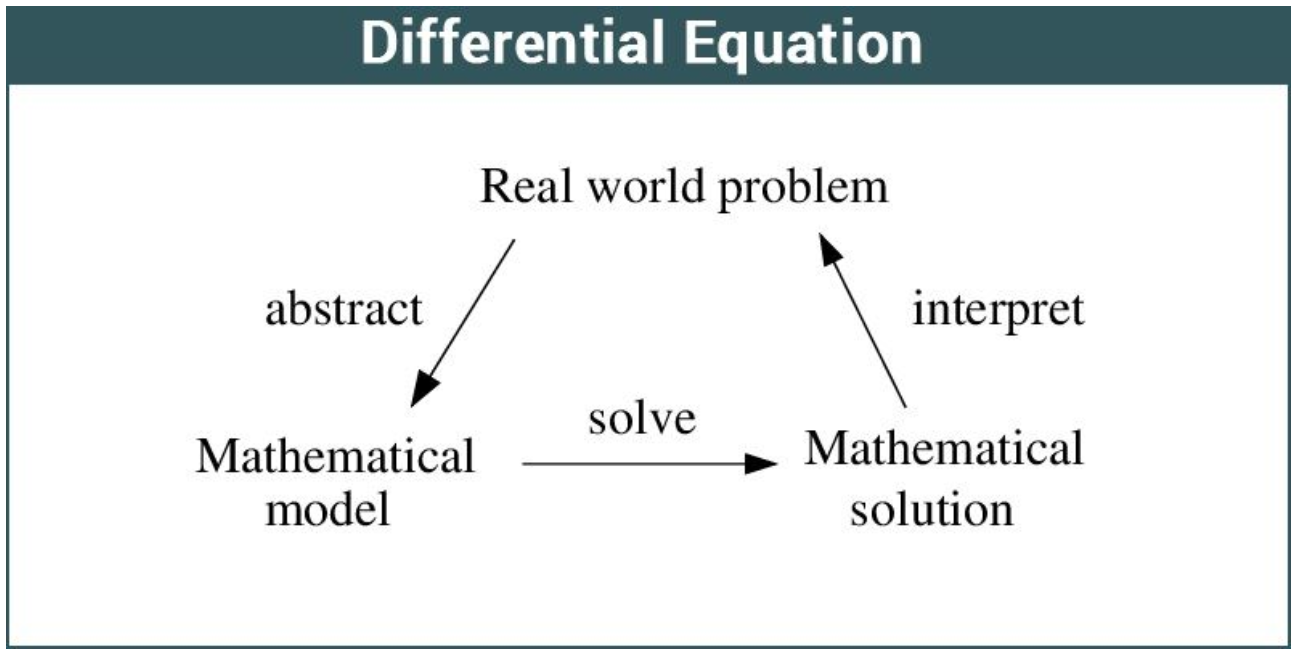(source: [https://byjus.com/maths/differential-equation/)](https://byjus.com/maths/differential-equation/)) 

### **1.2 Numerical solutions of ODE**

Consider the following **first order autonomous ODE with the initial condition:**

$\frac{\textrm{dy}}{\textrm{dt}}=\mathit{\mathbf{f}}\left(y\right),y\left(t_0 \right)=y_0$.

Then assume we partition the time interval $\left\lbrack 0,t_{\max } \right\rbrack$ equally as $0=t_0 <t_1 <\ldotp \ldotp \ldotp <t_N =t_{\max }$ with the time step size $h=\frac{t_{\max } }{N}$ . The aim is to find the numerical approximation $y_1 \;{,y}_2 ,\ldotp \ldotp \ldotp {,y}_N$, where $y_k$ approximates the true solution $y\left(t_k \right)$.

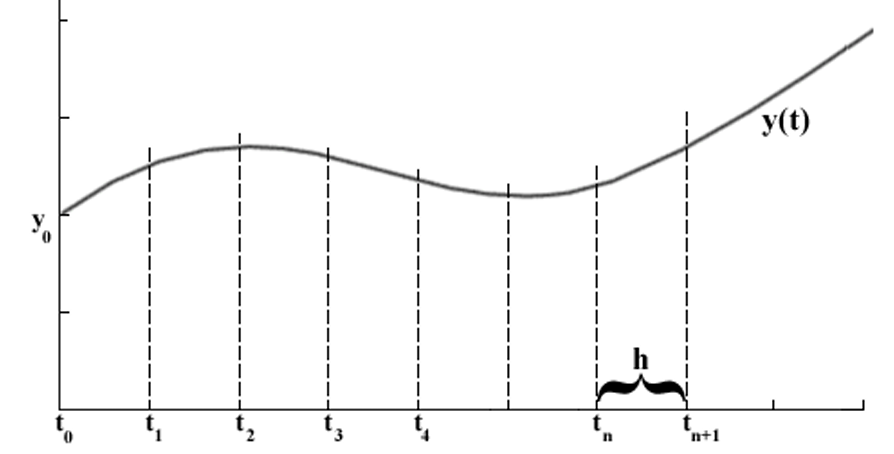

## **2. The forward Euler method** 

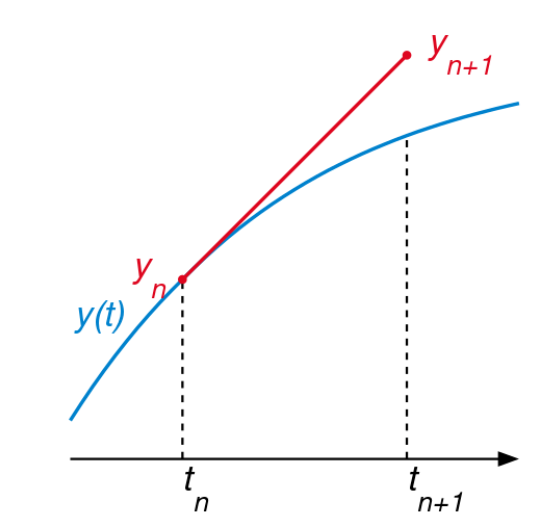(source: https://commons.wikimedia.org/wiki/File:Forward_Euler_method_illustration-2.svg)

Assume the velocity (or "slope") on the R.H.S. is a constant (the left-end value) in each small time interval, and the derivative on L.H.S. can be approximated by forward difference scheme:


$$\frac{y_{k+1} -y_k }{h}=f\left(y_k \right)$$


Thus we have the recursive formula:


$$y_{k+1} =y_k +h\;f\left(y_k \right)$$


(The corresponding MATLAB funtion has been defined at the end of this live script.)

### 2.1 One-dimension case

***Example 4***: $\;\frac{\textrm{dx}}{\textrm{dt}}=-x,x\left(0\right)=1$, where the exact solution is $x\left(t\right)=e^{-t}$.

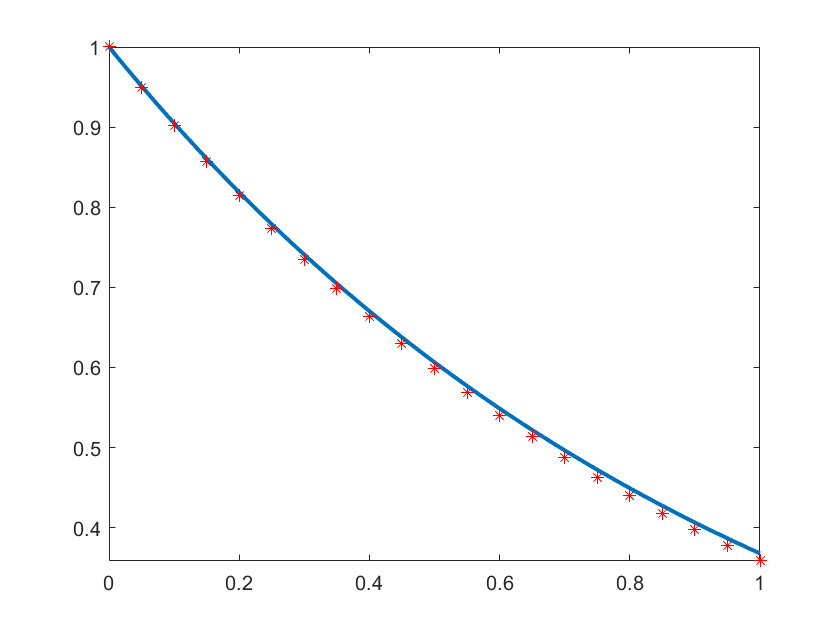

f = @(x) -x; % this is the R.H.S. of the ODE
x0 = 1;      % initial condition
N = 20;      % number of intervals
t_max = 1;   % ending time

[t,x] = euler_forward(f, t_max, x0, N);

fplot(@(t)exp(-t),[0 1],'LineWidth',2.0) % plot the real solution
hold on
plot(t,x,'r*') % plot your approximation 
hold off

***Example 5***:  [***Logistic growth model***](https://www.maa.org/press/periodicals/loci/joma/logistic-growth-model-background-logistic-modeling)

$\frac{\textrm{dP}}{\textrm{dt}}=\textrm{rP}\left(1-\frac{P}{K}\right)$ where $r$ and $K$ are two positive numbers (parameters).

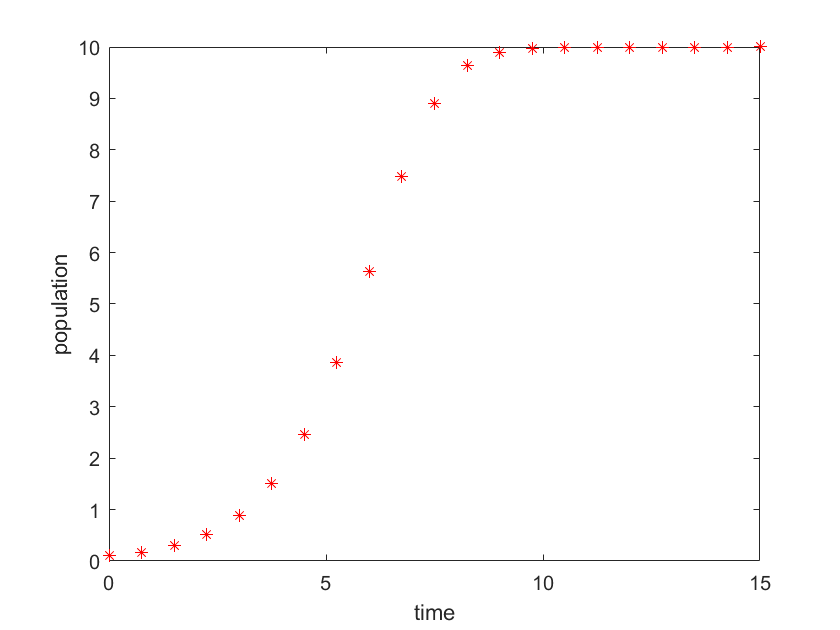

r = 1;
K = 10;
g = @(P) r*P*(1-P/K);

p0 = 0.1;    % initial condition
N = 20;     % number of intervals
t_max = 15;  % ending time

[t,p] = euler_forward(g, t_max, p0, N);
plot(t,p,'r*')
xlabel('time')
ylabel('population')

### 2.2 High-dimension case

***Example 6***: Prey-Predator Equation which is also called [Lotka-Volterra Equation](https://en.wikipedia.org/wiki/Lotka%E2%80%93Volterra_equations)


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=\alpha x-\beta \textrm{xy}\\
\frac{\textrm{dy}}{\textrm{dt}}=\delta \textrm{xy}-\gamma y
\end{array}$$


with initial conditon: $x\left(0\right)=y\left(0\right)=1$ 

x0 = [1;1]; % row vector for initial conditions

x0 =      1
     1


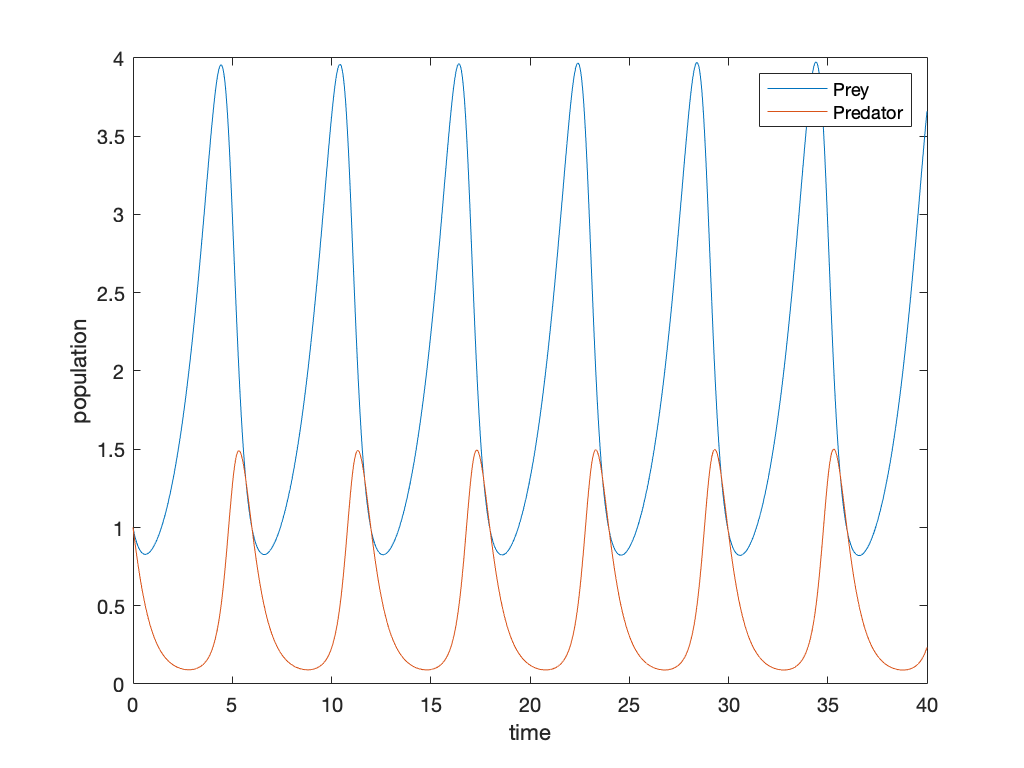

N = 1e5; % what about decrease N
t_max = 40;

alpha = 2/3;
beta = 4/3;
gamma = 1;
delta = 1;

% alternative 1
f= @(x)f_lv(x, alpha, beta, gamma, delta); % create the function handle

% alternative 2
% f = @(x)[alpha*x(1)-beta*x(1)*x(2); delta*x(1)*x(2)-gamma*x(2)]; % create the function handle directly

[t,x] = euler_forward(f, t_max, x0, N);
plot(t,x)
xlabel('time')
ylabel('population')
legend('Prey','Predator')

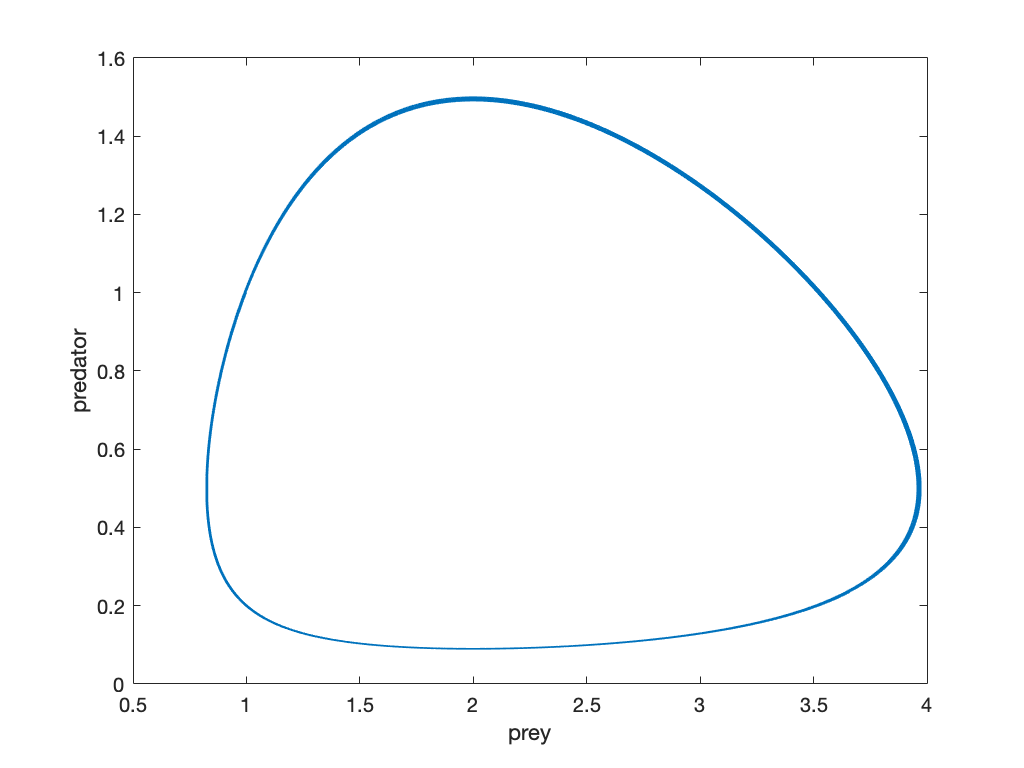

plot(x(1,:),x(2,:))
xlabel('prey')
ylabel('predator')

Exercise: change the initial value of y (predator) from 1 to 2 with stepsize 0.1, and see how the solution in phase plane changes.

### 2.3 Using MATLAB ODE Solver [ode23](https://www.mathworks.com/help/matlab/ref/ode23.html?s_tid=doc_ta#bu5ypsv_sep_shared-odefun)

Basic format: `[`[`t`](https://www.mathworks.com/help/matlab/ref/ode23.html?s_tid=doc_ta#bu5ypsv_sep_shared-t)`,`[`y`](https://www.mathworks.com/help/matlab/ref/ode23.html?s_tid=doc_ta#bu5ypsv_sep_shared-y)`] = ode23(`[`odefun`](https://www.mathworks.com/help/matlab/ref/ode23.html?s_tid=doc_ta#bu5ypsv_sep_shared-odefun)`,`[`tspan`](https://www.mathworks.com/help/matlab/ref/ode23.html?s_tid=doc_ta#bu5ypsv_sep_shared-tspan)`,`[`y0`](https://www.mathworks.com/help/matlab/ref/ode23.html?s_tid=doc_ta#bu5ypsv_sep_shared-y0)`)`

`"odefun" `-- Functions to solve. We define function `dydt = odefun(t,y)` at the end of the script.

`"tspan" `-- 1-by-2 vector `[t0 t_max]`.

`"y0" `-- initial conditions, if there are two variables, `y0` should be a 1-by-2 vector.

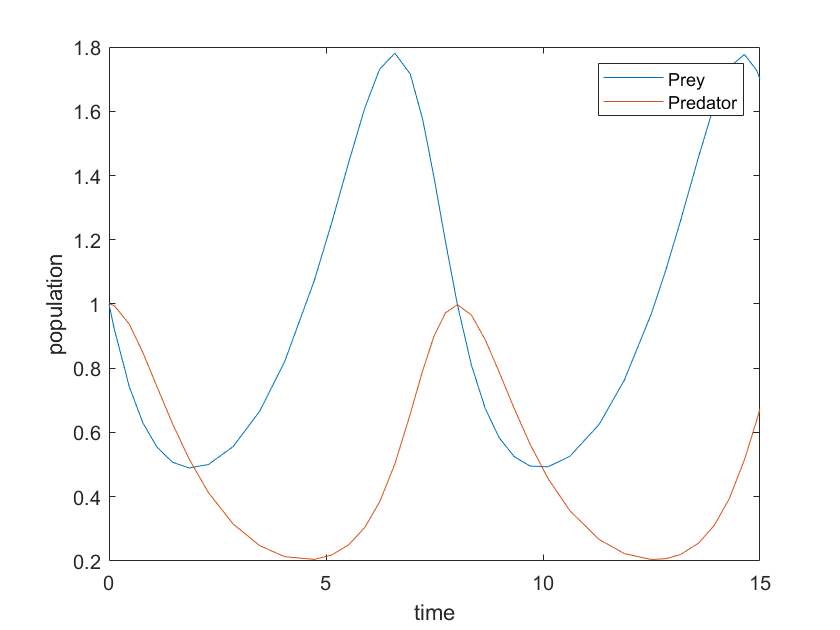

alpha = 2/3;
beta = 4/3;
gamma = 1;
delta = 1;

t0 = 0;
t_max = 15;
tspan = [t0 t_max];
x0 = [1 1];  

[t, x] = ode23(@(t, x)odefun(t, x, alpha, beta, gamma, delta), tspan, x0);

plot(t,x)
xlabel('time')
ylabel('population')
legend('Prey','Predator')

function [t,x] = euler_forward(f, t_max, x0, N)

    x = zeros(length(x0),N+1);
    x(:,1) = x0;
    h = t_max/N; %step size
    t = 0:h:t_max;
    
    for k = 1:N
        x(:, k+1) = x(:,k)+h*f(x(:,k));
    end

end


function output = f_lv(x, alpha, beta, gamma, delta)
    output = zeros(2,1);
    output(1) = alpha*x(1)-beta*x(1)*x(2);
    output(2) = delta*x(1)*x(2)-gamma*x(2);
end


function dydt = odefun(t, x, alpha, beta, gamma, delta)
    dydt = zeros(2,1);
    dydt(1) = alpha*x(1)-beta*x(1)*x(2);
    dydt(2) = delta*x(1)*x(2)-gamma*x(2);
end